# Peptide-target binding

clc
clearvars

## 1. Find the binding area similarity for ridigly docked peptides

### Load revelant data

#### Difference in SASA and total SASA of the peptide-protein rigid complex

load atp.mat
numatoms=[1505]; %number of atoms in every complex
for i=1:1
    rigid(i).delarea=reshape(readmatrix(['deltargetsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),70,[]);
    rigid(i).totarea=readmatrix(['totalsasa' num2str(i) '.txt'],"FileType","text","OutputType","double");
    rigid(i).atomlist=readtable(['atomtypes' num2str(i) '.txt']);
    temp=reshape(readmatrix(['delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]);
    [rigid(i).atomarea(:,1),rigid(i).atomarea(:,2),rigid(i).atomarea(:,3)]=find(temp); % [row,col,value]=find(X)
    %rigid(i).atomarea=abs(reshape(readmatrix(['delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]));
    clear temp
end

Error using reshape
Product of known dimensions, 1505, not divisible into total number of elements, 18167280.

#### Load the SASAs for the template protein-protein complex

templates=readmatrix("../wnsp12/central25bb.txt","FileType","text","OutputType","double")+1;
delarea=readmatrix("../wnsp12/delsasares.txt","FileType","text","OutputType","double"); 
sasa_temp=abs(delarea(end-70+1:end,templates));
clear delarea i numatoms templates

#### Calcuate the free energy 

(To be used when RAM is prohibitive, this script takes a while to run. The next block is much quicker and also very memory intensive)

T=310;
nsp12_7be=-38;% binding energy of NSP7-12 in kJ/mol
parfor i=1:1
    % Calculate entropy
    sume=0;
    l=length(rigid(i).atomarea(:,1));
    for j=1:l
        if j~=l
            ind=find(strcmp(atp.Type,rigid(i).atomlist.type(rigid(i).atomarea(j,1))));
            ent_a=atp.weight(ind,1)*(.539)*rigid(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            if rigid(i).atomarea(j+1,2)~=rigid(i).atomarea(j,2)
                rigid(i).entropy(rigid(i).atomarea(j,2))=sume;
                sume=0;
            end
        else
            ind=find(strcmp(atp.Type,rigid(i).atomlist.type(rigid(i).atomarea(j,1))));
            ent_a=atp.weight(ind)*(.539)*rigid(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            rigid(i).entropy(rigid(i).atomarea(j,2))=sume;
        end
    end
    rigid(i).entropy=rigid(i).entropy';
    %Load MMPBSA energies (enthalpy) and find binding free energy
    rigid(i).enthalpy=readmatrix(['mmpbsa' num2str(i) '.txt'],"FileType","text","OutputType","double","Range",[1 2]);
    rigid(i).be=rigid(i).enthalpy-rigid(i).entropy.*(T*4.19/1000);  %G=\delH-T\delS in kJ/mol
    minbe(i)=min(rigid(i).be);
end
refbe=min(minbe);
scale=nsp12_7be/refbe;

for i=1:1
    rigid(i).be=scale.*rigid(i).be;
end

Quicker calculations at the expense of higher computing costs and higher memory requirements. Benefits from parallelization overheads outweigh *parfor* outer loop calculations

### Find the weighted ensemble vector

KbT=2.577;
for i=1:1
    sum_be(i)=sum(exp(-rigid(i).be/KbT));
    for j=1:size(rigid(i).delarea,2)
        rigid(i).wsasa(:,j)=rigid(i).delarea(:,j)./rigid(i).totarea(j).*(exp(-rigid(i).be(j)/KbT)/sum_be(i));
    end
    rigid(i).vector=sum(rigid(i).wsasa,2);
end

### Cosine similarity

for i=1:size(sasa_temp,2)
    for j=1:1
        similarity(i,j)=dot(sasa_temp(:,i),rigid(j).vector)/(norm(sasa_temp(:,1)*norm(rigid(j).vector)));
    end
end

#### Plot heatmap

cmap=flipud(bone(10));
h=heatmap(similarity);
figure('Position', get(0, 'Screensize'))
h.XLabel='Peptides';
h.YLabel='NSP12-NSP7 central structures';
h.Title='Binding area similarity (rigidly docked)';
h.GridVisible = 'off';
h.FontSize=18;
h.ColorLimits=[0 ceil(max(max(similarity))*10)/10];
h.Colormap=cmap(1:ceil(max(max(similarity))*10),:);
%exportgraphics(h,'rigidpep_bind.eps','ContentType','vector','BackgroundColor','none')
exportgraphics(h,'rigidpep_bind.jpg','Resolution',900)

#### Complexes with the highest similarity

Compute the individual dot product

for k=1:size(sasa_temp,2)
    for i=1:1
        for j=1:size(rigid(i).wsasa,2)
            rigid(i).cosine(k,j)=dot(sasa_temp(:,k),rigid(i).wsasa(:,j))/(norm(sasa_temp(:,k))*norm(rigid(i).wsasa(:,j)));
        end
    end
end

Find the best structure

for i=1:1
    [~,rigid(i).best]=max(rigid(i).cosine,[],2);
end
save rigid.mat rigid

## 2. Binding similarity for flexpepdock peptides 

### Load revelant data

#### Difference in SASA and total SASA of the peptide-protein flexpep complex

clc
clearvars
load atp.mat
numatoms=[1256 1297 1289 1264]; %number of atoms in every complex
for i=1:4
    flexpep(i).delarea=reshape(readmatrix(['refined/deltargetsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),70,[]);
    flexpep(i).totarea=readmatrix(['refined/totalsasa' num2str(i) '.txt'],"FileType","text","OutputType","double");
    flexpep(i).atomlist=readtable(['refined/atomtypes' num2str(i) '.txt']);
    temp=reshape(readmatrix(['refined/delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]);
    [flexpep(i).atomarea(:,1),flexpep(i).atomarea(:,2),flexpep(i).atomarea(:,3)]=find(temp); % [row,col,value]=find(X)
    %flexpep(i).atomarea=abs(reshape(readmatrix(['delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]));
    clear temp
end

#### Load the SASAs for the template protein-protein complex

templates=readmatrix("../wnsp12/central25bb.txt","FileType","text","OutputType","double")+1;
delarea=readmatrix("../wnsp12/delsasares.txt","FileType","text","OutputType","double"); 
sasa_temp=abs(delarea(end-70+1:end,templates));
clear delarea i numatoms templates

#### Calcuate the free energy 

T=310;
nsp12_7be=-38;% binding energy of NSP7-12 in kJ/mol
parfor i=1:4
    % Calculate entropy
    sume=0;
    l=length(flexpep(i).atomarea(:,1));
    for j=1:l
        if j~=l
            ind=find(strcmp(atp.Type,flexpep(i).atomlist.type(flexpep(i).atomarea(j,1))));
            ent_a=atp.weight(ind,1)*(.539)*flexpep(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            if flexpep(i).atomarea(j+1,2)~=flexpep(i).atomarea(j,2)
                flexpep(i).entropy(flexpep(i).atomarea(j,2))=sume;
                sume=0;
            end
        else
            ind=find(strcmp(atp.Type,flexpep(i).atomlist.type(flexpep(i).atomarea(j,1))));
            ent_a=atp.weight(ind)*(.539)*flexpep(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            flexpep(i).entropy(flexpep(i).atomarea(j,2))=sume;
        end
    end
    flexpep(i).entropy=flexpep(i).entropy';
    %Load MMPBSA energies (enthalpy) and find binding free energy
    flexpep(i).enthalpy=readmatrix(['refined/mmpbsa' num2str(i) '.txt'],"FileType","text","OutputType","double","Range",[1 2]);
    flexpep(i).be=flexpep(i).enthalpy-flexpep(i).entropy.*(T*4.19/1000);  %G=\delH-T\delS in kJ/mol
    minbe(i)=min(flexpep(i).be);
end
refbe=min(minbe);
%scale=nsp12_7be/refbe;
scale=1;
for i=1:4
    flexpep(i).be=scale.*flexpep(i).be;
end

### Find the weighted ensemble vector

KbT=2.577;
for i=1:4
    sum_be(i)=sum(exp(-flexpep(i).be/KbT));
    for j=1:size(flexpep(i).delarea,2)
        flexpep(i).wsasa(:,j)=flexpep(i).delarea(:,j)./flexpep(i).totarea(j).*(exp(-flexpep(i).be(j)/KbT)/sum_be(i));
    end
    flexpep(i).vector=sum(flexpep(i).wsasa,2);
end

### Cosine similarity

for i=1:size(sasa_temp,2)
    for j=1:4
        similarity(i,j)=dot(sasa_temp(:,i),flexpep(j).vector)/(norm(sasa_temp(:,1)*norm(flexpep(j).vector)));
    end
end

#### Plot heatmap

cmap=flipud(bone(10));
h=heatmap(similarity);
figure('Position', get(0, 'Screensize'))
h.XLabel='Peptides';
h.YLabel='NSP12-NSP7 central structures';
h.Title='Binding area similarity (flexpep docked)';
h.GridVisible = 'off';
h.FontSize=18;
h.ColorLimits=[0 ceil(max(max(similarity))*10)/10];
h.Colormap=cmap(1:ceil(max(max(similarity))*10),:);
h.XData={'2','3','5','4'};
%exportgraphics(h,'flexpeppep_bind.eps','ContentType','vector','BackgroundColor','none')
%exportgraphics(h,'flexpep_bind.jpg','Resolution',900)

#### Complexes with the highest similarity

Compute the individual dot product

for k=1:size(sasa_temp,2)
    for i=1:4
        for j=1:size(flexpep(i).wsasa,2)
            flexpep(i).cosine(k,j)=dot(sasa_temp(:,k),flexpep(i).wsasa(:,j))/(norm(sasa_temp(:,k))*norm(flexpep(i).wsasa(:,j)));
        end
    end
end

Find the best structure

for i=1:4
    [~,flexpep(i).best]=max(flexpep(i).cosine,[],2);
end

## 3. Binding similarity for simulated peptides 

### Load revelant data

#### Difference in SASA and total SASA of the peptide-protein simulated complex

clc
clearvars
load atp.mat
numatoms=[1505]; %number of atoms in every complex
for i=1:1
    simu(i).delarea=reshape(readmatrix(['simulation/deltargetsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),71,[]);
    simu(i).totarea=readmatrix(['simulation/totalsasa' num2str(i) '.txt'],"FileType","text","OutputType","double");
    simu(i).atomlist=readtable(['simulation/atomtypes' num2str(i) '.txt']);
    temp=reshape(readmatrix(['simulation/delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]);
    [simu(i).atomarea(:,1),simu(i).atomarea(:,2),simu(i).atomarea(:,3)]=find(temp); % [row,col,value]=find(X)
    %simu(i).atomarea=abs(reshape(readmatrix(['delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]));
    clear temp
end

#### Load the SASAs for the template protein-protein complex

templates=readmatrix("../wnsp12/central25bb.txt","FileType","text","OutputType","double")+1;
delarea=readmatrix("../wnsp12/delsasares.txt","FileType","text","OutputType","double"); 
sasa_temp=abs(delarea(end-70+1:end,templates));
clear delarea i numatoms templates

#### Calcuate the free energy 

T=310;
nsp12_7be=-38;% binding energy of NSP7-12 in kJ/mol
parfor i=1:1
    % Calculate entropy
    sume=0;
    l=length(simu(i).atomarea(:,1));
    for j=1:l
        if j~=l
            ind=find(strcmp(atp.Type,simu(i).atomlist.type(simu(i).atomarea(j,1))));
            ent_a=atp.weight(ind,1)*(.539)*simu(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            if simu(i).atomarea(j+1,2)~=simu(i).atomarea(j,2)
                simu(i).entropy(simu(i).atomarea(j,2))=sume;
                sume=0;
            end
        else
            ind=find(strcmp(atp.Type,simu(i).atomlist.type(simu(i).atomarea(j,1))));
            ent_a=atp.weight(ind)*(.539)*simu(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            simu(i).entropy(simu(i).atomarea(j,2))=sume;
        end
    end
     simu(i).entropy=simu(i).entropy';
     %Load MMPBSA energies (enthalpy) and find binding free energy
     simu(i).enthalpy=readmatrix(['simulation/mmpbsa' num2str(i) '.txt'],"FileType","text","OutputType","double");
     simu(i).be=simu(i).enthalpy-simu(i).entropy.*(T*4.19/1000);  %G=\delH-T\delS in kJ/mol
     minbe(i)=min(simu(i).be);
  end
 refbe=min(minbe);
scale=nsp12_7be/refbe
scale=1;
for i=1:1
    simu(i).be=scale.*simu(i).be;
end

### Find the weighted ensemble vector

KbT=2.577;
for i=1:1
    sum_be(i)=sum(exp(-simu(i).be/KbT));
    for j=1:size(simu(i).delarea,2)
        simu(i).wsasa(:,j)=simu(i).delarea(:,j)./simu(i).totarea(j).*(exp(-simu(i).be(j)/KbT)/sum_be(i));
    end
    simu(i).vector=sum(simu(i).wsasa,2);
end

### Cosine similarity

for i=1:size(sasa_temp,2)
    for j=1:1
        similarity(i,j)=dot(sasa_temp(:,i),simu(j).vector)/(norm(sasa_temp(:,1)*norm(simu(j).vector)));
    end
end

#### Plot heatmap

cmap=flipud(bone(10));
h=heatmap(similarity);
figure('Position', get(0, 'Screensize'))
h.XLabel='Peptides';
h.YLabel='NSP12-NSP7 central structures';
h.Title='Binding area similarity (simulation)';
h.GridVisible = 'off';
h.FontSize=18;
h.XData={'2_A','2_B','3_A','3_B','5_A','5_B','4'};
h.ColorLimits=[0 ceil(max(max(similarity))*10)/10];
h.Colormap=cmap(1:ceil(max(max(similarity))*10),:);
%exportgraphics(h,'simupep_bind.eps','ContentType','vector','BackgroundColor','none')
%exportgraphics(h,'simu_bind.jpg','Resolution',900)

#### Complexes with the highest similarity

Compute the individual dot product

for k=1:size(sasa_temp,2)
    for i=1:1
        for j=1:size(simu(i).wsasa,2)
            simu(i).cosine(k,j)=dot(sasa_temp(:,k),simu(i).wsasa(:,j))/(norm(sasa_temp(:,k))*norm(simu(i).wsasa(:,j)));
        end
    end
end

Find the best structure

for i=1:1
    [~,simu(i).best]=max(simu(i).cosine,[],2);
end

## 4. Binding similarity for simulated (merged) peptides 

### Load revelant data

#### Difference in SASA and total SASA of the peptide-protein simulated complex

clc
clearvars
load atp.mat
numatoms=[1256 1297 1289 1264]; %number of atoms in every complex
for i=1:4
    simu(i).delarea=reshape(readmatrix(['simulation_m/deltargetsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),70,[]);
    simu(i).totarea=readmatrix(['simulation_m/totalsasa' num2str(i) '.txt'],"FileType","text","OutputType","double");
    simu(i).atomlist=readtable(['simulation_m/atomtypes' num2str(i) '.txt']);
    temp=reshape(readmatrix(['simulation_m/delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]);
    [simu(i).atomarea(:,1),simu(i).atomarea(:,2),simu(i).atomarea(:,3)]=find(temp); % [row,col,value]=find(X)
    %simu(i).atomarea=abs(reshape(readmatrix(['delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]));
    clear temp
end

#### Load the SASAs for the template protein-protein complex

templates=readmatrix("../wnsp12/central25bb.txt","FileType","text","OutputType","double")+1;
delarea=readmatrix("../wnsp12/delsasares.txt","FileType","text","OutputType","double"); 
sasa_temp=abs(delarea(end-70+1:end,templates));
clear delarea i numatoms templates

#### Calcuate the free energy 

T=310;
nsp12_7be=-38;% binding energy of NSP7-12 in kJ/mol
parfor i=1:4
    % Calculate entropy
    sume=0;
    l=length(simu(i).atomarea(:,1));
    for j=1:l
        if j~=l
            ind=find(strcmp(atp.Type,simu(i).atomlist.type(simu(i).atomarea(j,1))));
            ent_a=atp.weight(ind,1)*(.539)*simu(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            if simu(i).atomarea(j+1,2)~=simu(i).atomarea(j,2)
                simu(i).entropy(simu(i).atomarea(j,2))=sume;
                sume=0;
            end
        else
            ind=find(strcmp(atp.Type,simu(i).atomlist.type(simu(i).atomarea(j,1))));
            ent_a=atp.weight(ind)*(.539)*simu(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            simu(i).entropy(simu(i).atomarea(j,2))=sume;
        end
    end
     simu(i).entropy=simu(i).entropy';
     %Load MMPBSA energies (enthalpy) and find binding free energy
     simu(i).enthalpy=readmatrix(['simulation_m/mmpbsa' num2str(i) '.txt'],"FileType","text","OutputType","double");
     simu(i).be=simu(i).enthalpy-simu(i).entropy.*(T*4.19/1000);  %G=\delH-T\delS in kJ/mol
     minbe(i)=min(simu(i).be);
  end
 refbe=min(minbe);
scale=nsp12_7be/refbe

scale = 0.5042

scale=1;
for i=1:4
    simu(i).be=scale.*simu(i).be;
end

### Find the weighted ensemble vector

KbT=2.577;
for i=1:4
    sum_be(i)=sum(exp(-simu(i).be/KbT));
    for j=1:size(simu(i).delarea,2)
        simu(i).wsasa(:,j)=simu(i).delarea(:,j)./simu(i).totarea(j).*(exp(-simu(i).be(j)/KbT)/sum_be(i));
    end
    simu(i).vector=sum(simu(i).wsasa,2);
end

### Cosine similarity

for i=1:size(sasa_temp,2)
    for j=1:4
        similarity(i,j)=dot(sasa_temp(:,i),simu(j).vector)/(norm(sasa_temp(:,1)*norm(simu(j).vector)));
    end
end

#### Plot heatmap

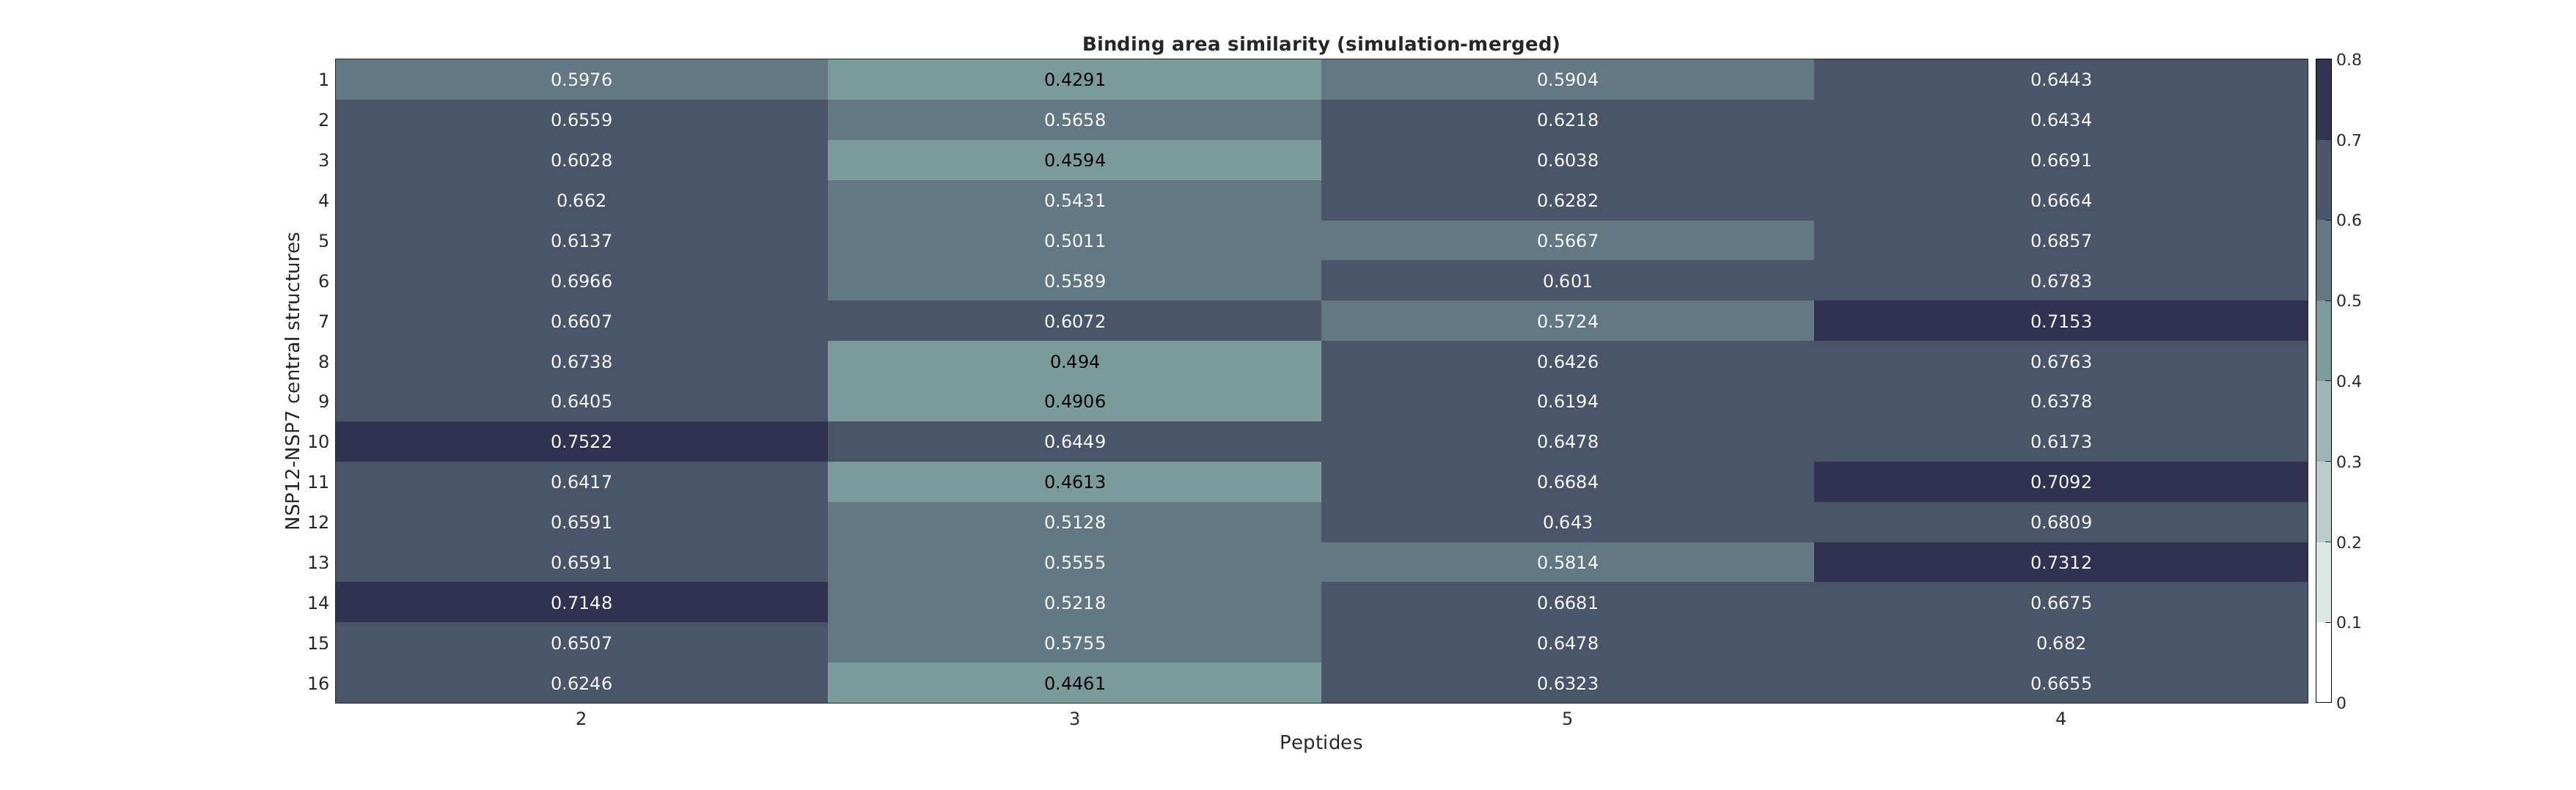

cmap=flipud(bone(10));
h=heatmap(similarity);
figure('Position', get(0, 'Screensize'))
h.XLabel='Peptides';
h.YLabel='NSP12-NSP7 central structures';
h.Title='Binding area similarity (simulation-merged)';
h.GridVisible = 'off';
h.FontSize=18;
h.XData={'2','3','5','4'};
h.ColorLimits=[0 ceil(max(max(similarity))*10)/10];
h.Colormap=cmap(1:ceil(max(max(similarity))*10),:);

%exportgraphics(h,'simupep_bind.eps','ContentType','vector','BackgroundColor','none')
%exportgraphics(h,'simu_bind.jpg','Resolution',900)

#### Complexes with the highest similarity

Compute the individual dot product

for k=1:size(sasa_temp,2)
    for i=1:1
        for j=1:size(simu(i).wsasa,2)
            simu(i).cosine(k,j)=dot(sasa_temp(:,k),simu(i).wsasa(:,j))/(norm(sasa_temp(:,k))*norm(simu(i).wsasa(:,j)));
        end
    end
end

Find the best structure

for i=1:1
    [~,simu(i).best]=max(simu(i).cosine,[],2);
end

## 5. Analysis

clc
clearvars

load simulation/simu.mat
load simulation_m/simu_m.mat

load ../mmpbsa/mmpbsa_sort.mat
load ../mmpbsa/bind_ent.mat
T=310;
mmpbsa_sort(:,7)=-T.*bind_ent*(4.19/1000);
mmpbsa_sort(:,8)=mmpbsa_sort(:,6)+mmpbsa_sort(:,7);
clear bind_ent


clf
%plot(1:8334,mmpbsa_sort(:,8))
plot(1:8334,movmean(mmpbsa_sort(:,8),100))
subplot(3,1,1)
hold on
stem(1:400,simu_m(1).be,'Marker',"o",'Color','r')
stem(1:400,simu_m(2).be,'Marker',"o",'Color','b')
stem(1:400,simu_m(3).be,'Marker',"o",'Color','g')
yline(-38)
xline(200)
title('Total Binding energy (kJ/mol)')
legend
hold off
subplot(3,1,2)
hold on
stem(1:400,simu_m(1).enthalpy,'Marker','o','Color','r')
stem(1:400,simu_m(2).enthalpy,'Marker','o','Color','b')
stem(1:400,simu_m(3).enthalpy,'Marker','o','Color','g')
xline(200)
title('Binding enthaply (kJ/mol)')
hold off
subplot(3,1,3)
hold on 
stem(1:400,simu_m(1).entropy.*1.302,'Marker','o','Color','r')
stem(1:400,simu_m(2).entropy.*1.302,'Marker','o','Color','b')
stem(1:400,simu_m(3).entropy.*1.302,'Marker','o','Color','g')
xline(200)
title('Binding Entropy (T\DeltaS) (kJ/mol)')
hold off

% stem(1:400',simu_m(1).entropy*1.302)
% hold on
% stem(1:400',simu_m(2).entropy*1.302)
% stem(1:400',simu_m(3).entropy.*1.302)
% %yline(mean(mmpbsa_sort(:,8)))
% hold off
% plot(1:400',simu_m(1).entropy*1.302,1:400',simu_m(2).entropy*1.302,1:400',simu_m(3).entropy*1.302)
% hold on
% plot(1:400',simu_m(1).be,1:400',simu_m(2).be,1:400',simu_m(3).be)
% plot(1:8334,mmpbsa_sort(:,8))
% hold off

## 6. Binding similarity for kb1-nsp7

### Load revelant data

#### Difference in SASA and total SASA of the peptide-protein simulated complex

clc
clearvars
load atp.mat
numatoms=[1505]; %number of atoms in every complex
for i=1:1
    simu(i).delarea=reshape(readmatrix(['kb1_nsp7/deltargetsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),71,[]);
    simu(i).totarea=readmatrix(['kb1_nsp7/totalsasa' num2str(i) '.txt'],"FileType","text","OutputType","double");
    simu(i).atomlist=readtable(['kb1_nsp7/atomtypes' num2str(i) '.txt']);
    temp=reshape(readmatrix(['kb1_nsp7/delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]);
    [simu(i).atomarea(:,1),simu(i).atomarea(:,2),simu(i).atomarea(:,3)]=find(temp); % [row,col,value]=find(X)
    %simu(i).atomarea=abs(reshape(readmatrix(['delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]));
    clear temp
end

#### Load the SASAs for the template protein-protein complex

templates=readmatrix("../wnsp12/central25bb.txt","FileType","text","OutputType","double")+1;
delarea=readmatrix("../wnsp12/delsasares.txt","FileType","text","OutputType","double"); 
sasa_temp=abs(delarea(end-70+1:end,templates));
sasa_temp=[zeros(1,16); sasa_temp];
clear delarea i numatoms templates

#### Calcuate the free energy 

T=310;
nsp12_7be=-38;% binding energy of NSP7-12 in kJ/mol
for i=1:1
    % Calculate entropy
    sume=0;
    l=length(simu(i).atomarea(:,1));
    for j=1:l
        if j~=l
            ind=find(strcmp(atp.Type,simu(i).atomlist.type(simu(i).atomarea(j,1))));
            ent_a=atp.weight(ind,1)*(.539)*simu(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            if simu(i).atomarea(j+1,2)~=simu(i).atomarea(j,2)
                simu(i).entropy(simu(i).atomarea(j,2))=sume;
                sume=0;
            end
        else
            ind=find(strcmp(atp.Type,simu(i).atomlist.type(simu(i).atomarea(j,1))));
            ent_a=atp.weight(ind)*(.539)*simu(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            simu(i).entropy(simu(i).atomarea(j,2))=sume;
        end
    end
     simu(i).entropy=simu(i).entropy';
     %Load MMPBSA energies (enthalpy) and find binding free energy
     simu(i).enthalpy=readmatrix(['kb1_nsp7/mmpbsa_final' num2str(i) '.txt'],"FileType","text","OutputType","double");
     simu(i).enthalpy(:,1)=[];
     simu(i).be=simu(i).enthalpy-simu(i).entropy.*(T*4.19/1000);  %G=\delH-T\delS in kJ/mol
     minbe(i)=min(simu(i).be);
end

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.

 refbe=min(minbe);
scale=nsp12_7be/refbe

scale = 0.0407

scale=1;
for i=1:1
    simu(i).be=scale.*simu(i).be;
end

### Find the weighted ensemble vector

KbT=2.577;
for i=1:1
    sum_be(i)=sum(exp(-simu(i).be/KbT));
    for j=1:size(simu(i).delarea,2)
        simu(i).wsasa(:,j)=simu(i).delarea(:,j)./simu(i).totarea(j).*(exp(-simu(i).be(j)/KbT)/sum_be(i));
    end
    simu(i).vector=sum(simu(i).wsasa,2);
end

### Cosine similarity

for i=1:size(sasa_temp,2)
    for j=1:1
        similarity(i,j)=dot(sasa_temp(:,i),simu(j).vector)/(norm(sasa_temp(:,1)*norm(simu(j).vector)));
    end
end

#### Plot heatmap

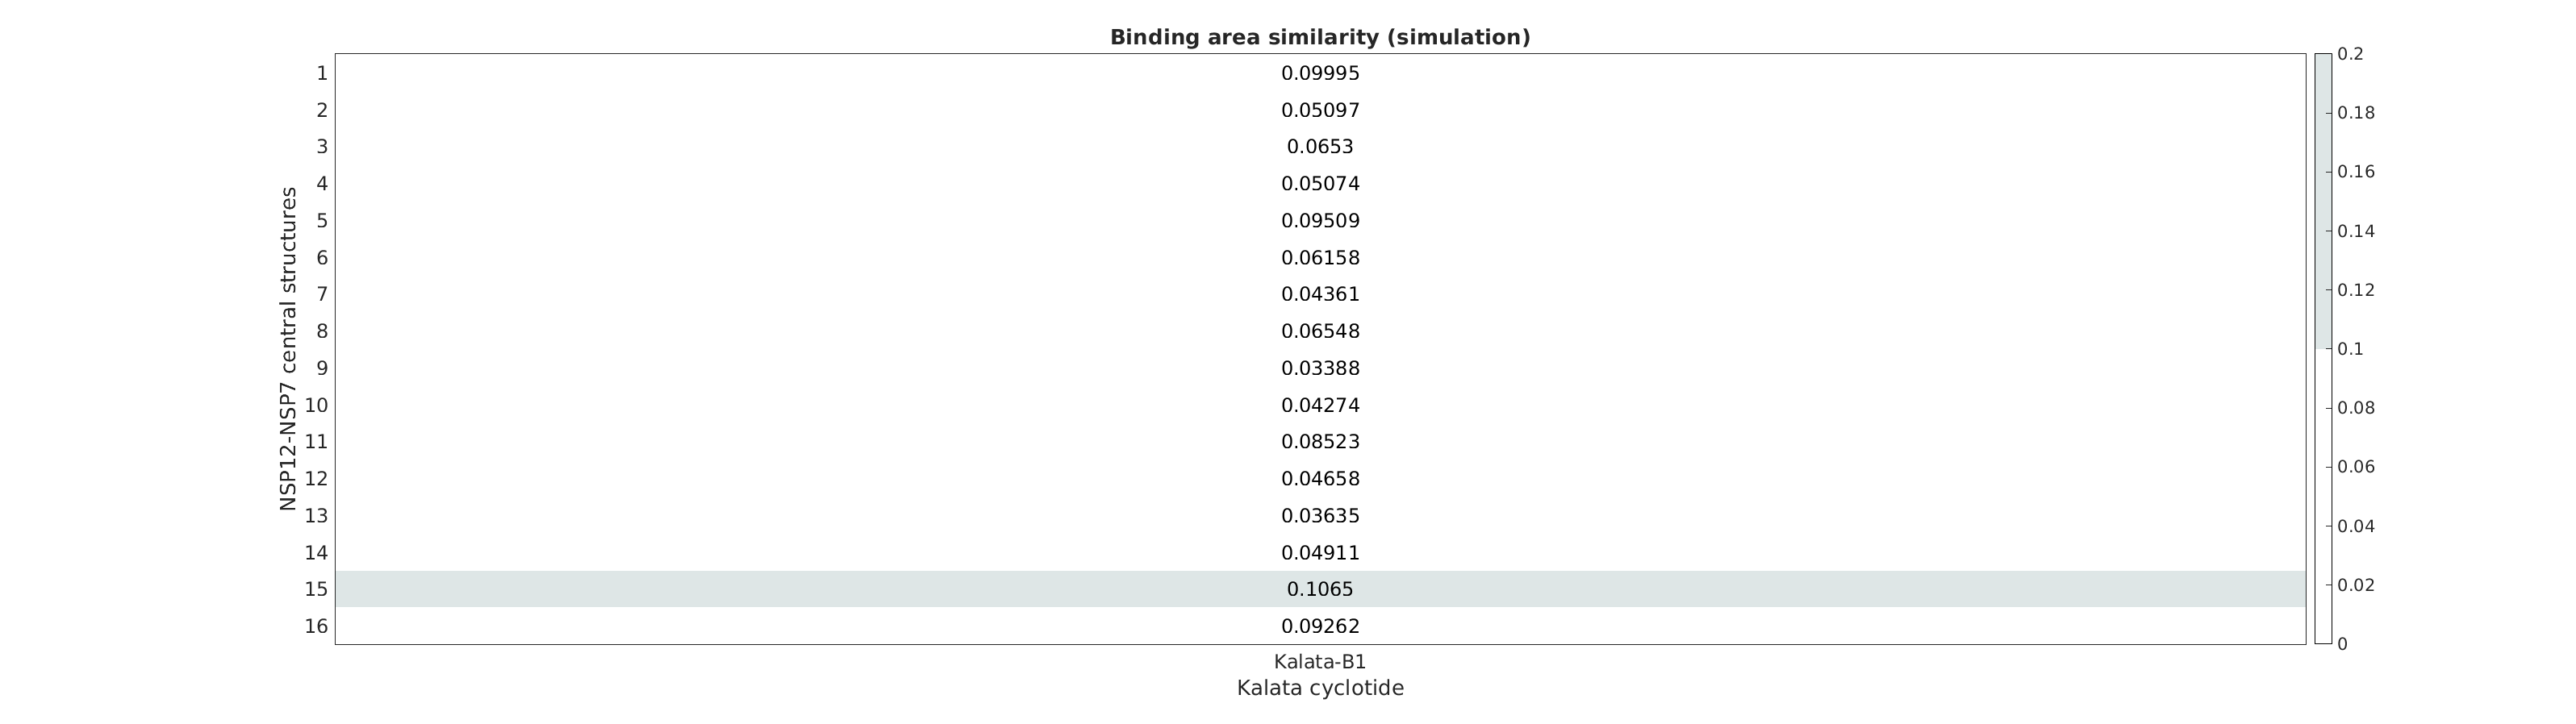

cmap=flipud(bone(10));
h=heatmap(similarity);
figure('Position', get(0, 'Screensize'))
h.XLabel='Kalata cyclotide';
h.YLabel='NSP12-NSP7 central structures';
h.Title='Binding area similarity (simulation)';
h.GridVisible = 'off';
h.FontSize=18;
h.XData={'Kalata-B1'};
h.ColorLimits=[0 ceil(max(max(similarity))*10)/10];
h.Colormap=cmap(1:ceil(max(max(similarity))*10),:);

%exportgraphics(h,'simupep_bind.eps','ContentType','vector','BackgroundColor','none')
exportgraphics(h,'kb1nsp7.jpg','Resolution',900)

#### Complexes with the highest similarity

Compute the individual dot product

for k=1:size(sasa_temp,2)
    for i=1:1
        for j=1:size(simu(i).wsasa,2)
            simu(i).cosine(k,j)=dot(sasa_temp(:,k),simu(i).wsasa(:,j))/(norm(sasa_temp(:,k))*norm(simu(i).wsasa(:,j)));
        end
    end
end

Find the best structure

for i=1:1
    [~,simu(i).best]=max(simu(i).cosine,[],2);
end

## 7. Binding similarity for kb1-chC1

### Load revelant data

#### Difference in SASA and total SASA of the peptide-protein simulated complex

clc
clearvars
load atp.mat
numatoms=[1505]; %number of atoms in every complex
for i=1:1
    simu(i).delarea=reshape(readmatrix(['kb1_chC1/deltargetsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),71,[]);
    simu(i).totarea=readmatrix(['kb1_chC1/totalsasa' num2str(i) '.txt'],"FileType","text","OutputType","double");
    simu(i).atomlist=readtable(['kb1_chC1/atomtypes' num2str(i) '.txt']);
    temp=reshape(readmatrix(['kb1_chC1/delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]);
    [simu(i).atomarea(:,1),simu(i).atomarea(:,2),simu(i).atomarea(:,3)]=find(temp); % [row,col,value]=find(X)
    %simu(i).atomarea=abs(reshape(readmatrix(['delatomsasa' num2str(i) '.txt'],"FileType","text","OutputType","double"),numatoms(i),[]));
    clear temp
end

#### Load the SASAs for the template protein-protein complex

templates=readmatrix("../wnsp12/central25bb.txt","FileType","text","OutputType","double")+1;
delarea=readmatrix("../wnsp12/delsasares.txt","FileType","text","OutputType","double"); 
sasa_temp=abs(delarea(end-70+1:end,templates));
sasa_temp=[zeros(1,16); sasa_temp];
clear delarea i numatoms templates

#### Calcuate the free energy 

T=310;
nsp12_7be=-38;% binding energy of NSP7-12 in kJ/mol
for i=1:1
    % Calculate entropy
    sume=0;
    l=length(simu(i).atomarea(:,1));
    for j=1:l
        if j~=l
            ind=find(strcmp(atp.Type,simu(i).atomlist.type(simu(i).atomarea(j,1))));
            ent_a=atp.weight(ind,1)*(.539)*simu(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            if simu(i).atomarea(j+1,2)~=simu(i).atomarea(j,2)
                simu(i).entropy(simu(i).atomarea(j,2))=sume;
                sume=0;
            end
        else
            ind=find(strcmp(atp.Type,simu(i).atomlist.type(simu(i).atomarea(j,1))));
            ent_a=atp.weight(ind)*(.539)*simu(i).atomarea(j,3)*100;
            sume=sume+ent_a;
            simu(i).entropy(simu(i).atomarea(j,2))=sume;
        end 
    end
     simu(i).entropy=simu(i).entropy';
     %Load MMPBSA energies (enthalpy) and find binding free energy
     simu(i).enthalpy=readmatrix(['kb1_chC1/mmpbsa_final' num2str(i) '.txt'],"FileType","text","OutputType","double");
     simu(i).enthalpy(:,1)=[];
     simu(i).be=simu(i).enthalpy-simu(i).entropy.*(T*4.19/1000);  %G=\delH-T\delS in kJ/mol
     minbe(i)=min(simu(i).be);
end
refbe=min(minbe);
scale=nsp12_7be/refbe

scale = 0.3098

scale=1;
for i=1:1
    simu(i).be=scale.*simu(i).be;
end

### Find the weighted ensemble vector

KbT=2.577;
for i=1:1
    sum_be(i)=sum(exp(-simu(i).be/KbT));
    for j=1:size(simu(i).delarea,2)
        simu(i).wsasa(:,j)=simu(i).delarea(:,j)./simu(i).totarea(j).*(exp(-simu(i).be(j)/KbT)/sum_be(i));
    end
    simu(i).vector=sum(simu(i).wsasa,2);
end

### Cosine similarity

for i=1:size(sasa_temp,2)
    for j=1:1
        similarity(i,j)=dot(sasa_temp(:,i),simu(j).vector)/(norm(sasa_temp(:,1)*norm(simu(j).vector)));
    end
end

#### Plot heatmap

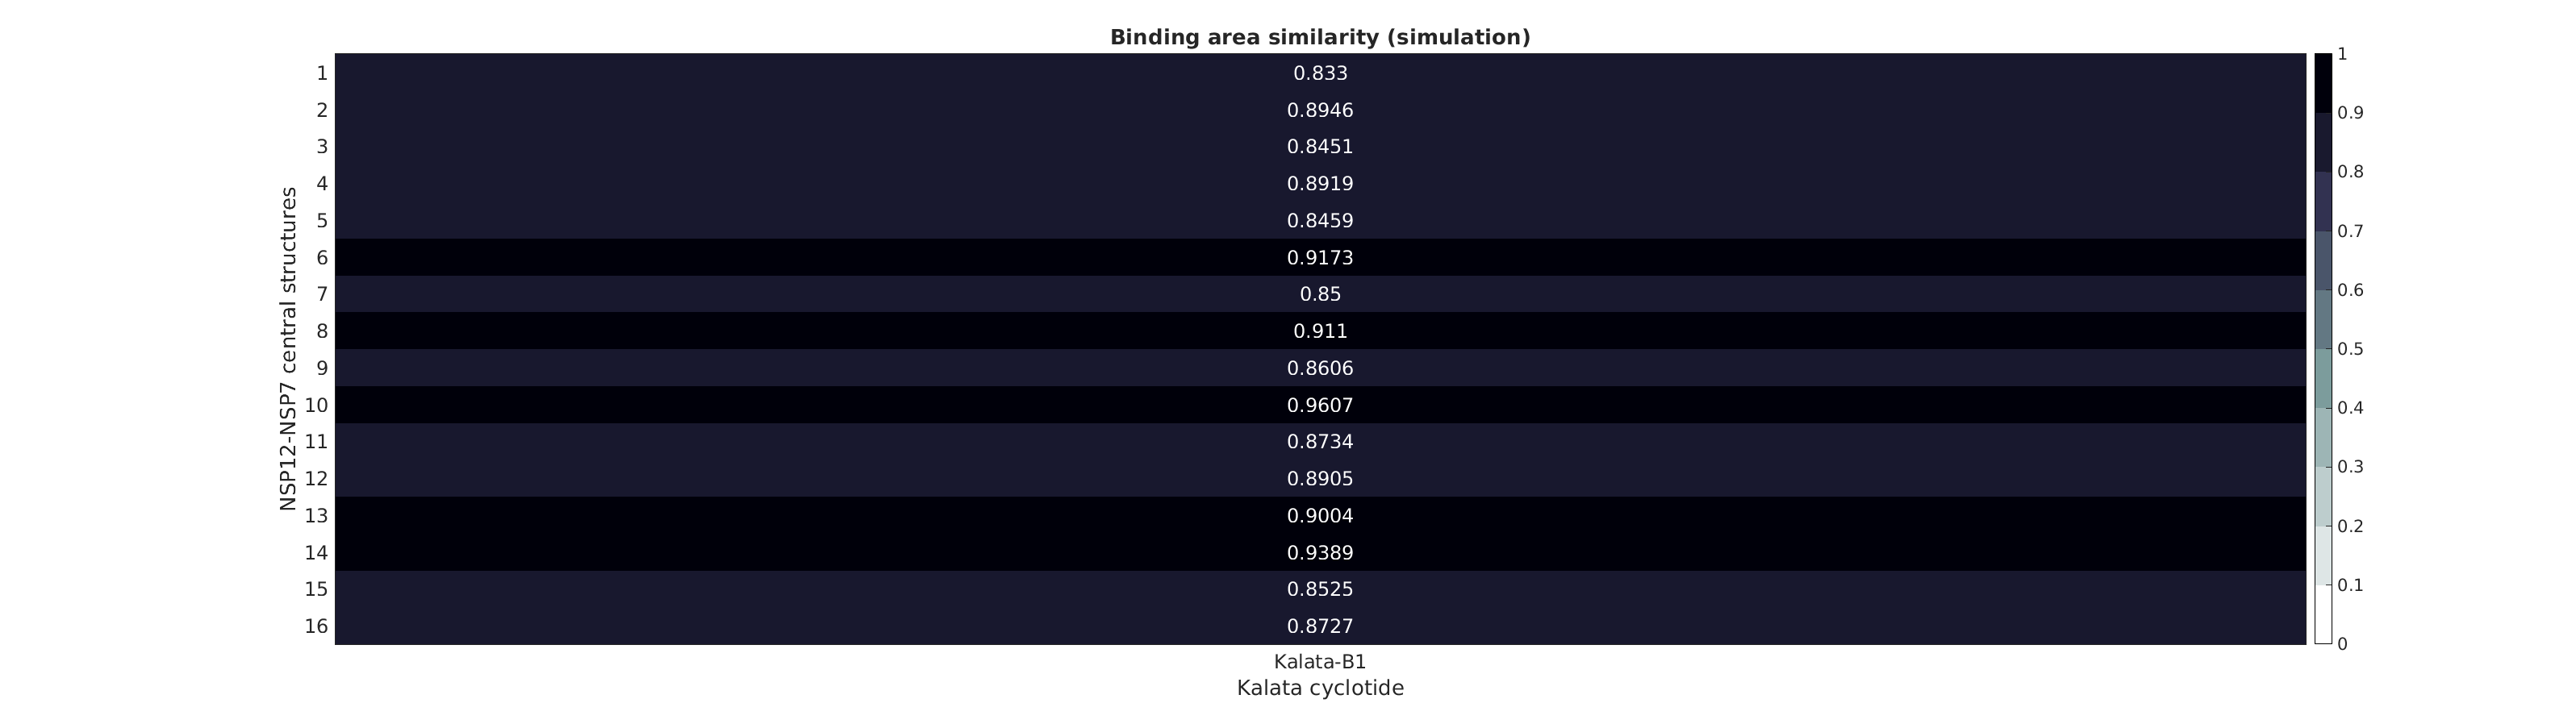

cmap=flipud(bone(10));
h=heatmap(similarity);
figure('Position', get(0, 'Screensize'))
h.XLabel='Kalata cyclotide';
h.YLabel='NSP12-NSP7 central structures';
h.Title='Binding area similarity (simulation)';
h.GridVisible = 'off';
h.FontSize=18;
h.XData={'Kalata-B1'};
h.ColorLimits=[0 ceil(max(max(similarity))*10)/10];
h.Colormap=cmap(1:ceil(max(max(similarity))*10),:);
%exportgraphics(h,'simupep_bind.eps','ContentType','vector','BackgroundColor','none')
exportgraphics(h,'kb1chC1.jpg','Resolution',900)

#### Complexes with the highest similarity

Compute the individual dot product

for k=1:size(sasa_temp,2)
    for i=1:1
        for j=1:size(simu(i).wsasa,2)
            simu(i).cosine(k,j)=dot(sasa_temp(:,k),simu(i).wsasa(:,j))/(norm(sasa_temp(:,k))*norm(simu(i).wsasa(:,j)));
        end
    end
end

Find the best structure

for i=1:1
    [~,simu(i).best]=max(simu(i).cosine,[],2);
end